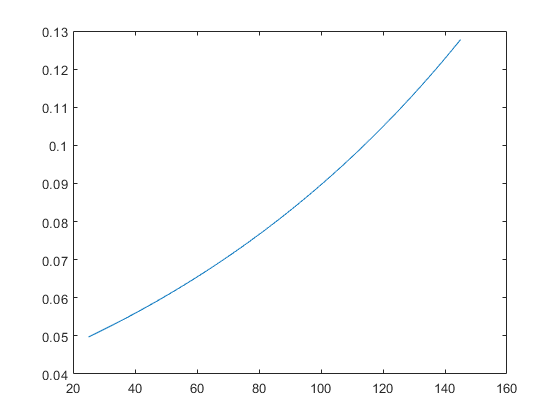

Tj = 25:145;
Ta = 20;
Rheatsink = 2.9;
Rtim = 2.5;
Rjc = 0.5;

Rtotal = 0.05*0.8167*exp(0.007865.*Tj);

Ploss = (Tj - Ta)./ (Rheatsink + Rtim + Rjc);
Isource = sqrt(Ploss./Rtotal);
figure
hold off
plot(Tj, Rtotal)

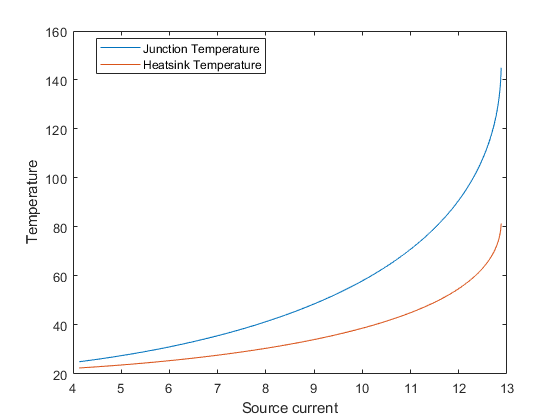

plot(Isource,Tj)
ylabel('Temperature')
xlabel('Source current')
hold on
plot(Isource,Ploss.*Rheatsink +Ta)
legend('Junction Temperature','Heatsink Temperature','Location', 'best');
hold off

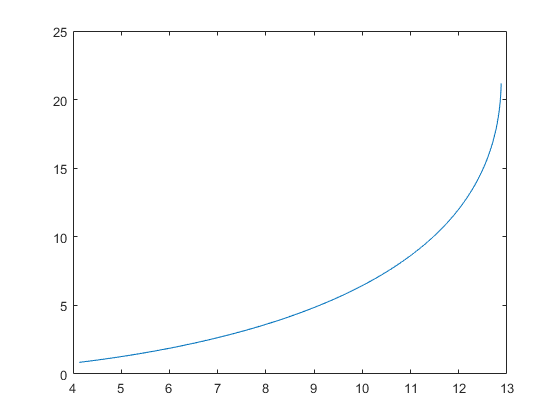

plot(Isource,Ploss)


k = 1;
for I = 0:0.1:20
    j = 1;
    for Tj = 100:0.1:145
        P(k,j) = I^2*0.05*0.8167*exp(0.007865.*Tj);
        if abs(Tj - (Ta + P(k,j)*(Rtim + Rheatsink + Rjc))) > 0.4
            P(k,j) = -999;
        else
            fprintf("Temperature is %f, current is %f, power loss is %f \n",Tj,I,P(k,j)/4)
        end
        j = j + 1;
    end
    k = k + 1;
end

Temperature is 100.000000, current is 12.300000, power loss is 3.391216 
Temperature is 100.100000, current is 12.300000, power loss is 3.393884 
Temperature is 100.200000, current is 12.300000, power loss is 3.396554 
Temperature is 100.300000, current is 12.300000, power loss is 3.399227 
Temperature is 100.400000, current is 12.300000, power loss is 3.401901 
Temperature is 100.500000, current is 12.300000, power loss is 3.404578 
Temperature is 100.600000, current is 12.300000, power loss is 3.407257 
Temperature is 100.700000, current is 12.300000, power loss is 3.409937 
Temperature is 100.800000, current is 12.300000, power loss is 3.412620 
Temperature is 100.900000, current is 12.300000, power loss is 3.415305 
Temperature is 101.000000, current is 12.300000, power loss is 3.417993 
Temperature is 101.100000, current is 12.300000, power loss is 3.420682 
Temperature is 102.700000, current is 12.400000, power loss is 3.520554 
Temperature is 102.800000, current is 12.400000, po

%plot3(65:145,0:0.1:20,P)
%xlabel('Temperature')
%ylabel('Current')
%zlabel('Loss')